# Concept demonstrator - **stencils**

In this script we'll take a closer look at the stencil derivation for one specific NODE type.  We'll then compare the results of this derivation to the stencils produced by the  [`bh_get_node_stencils`](matlab:  edit bh_get_node_stencils) function.

Create Thermal and Geometry parameters

OBJ_params = bh_sys_params_CLS("bh_PARAMS_DATABASE.xlsx", "SET_1");

OBJ_params.Delta_X = 0.001; 
OBJ_params.Delta_Y = 0.001; 

## Create a table of Thermal stencils

Compute a table of the Thermal stencils for our different NODE Types using the the [`bh_get_node_stencils`](matlab:  edit bh_get_node_stencils) function

- **ATTENTION:**  will take approx 1 minute to compute

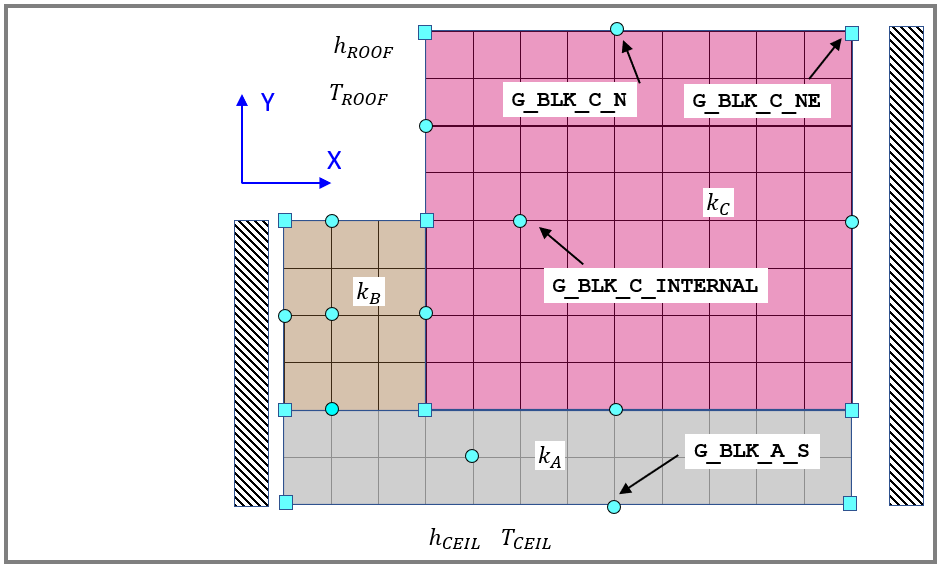

sten_TAB = bh_get_node_stencils(OBJ_params)


 ... Finished [ 1] of 23 :  NODE_TYPE = G_BLK_B_INTERNAL
 ... Finished [ 2] of 23 :  NODE_TYPE = G_BLK_B_NW
 ... Finished [ 3] of 23 :  NODE_TYPE = G_BLK_B_N
 ... Finished [ 4] of 23 :  NODE_TYPE = G_BLK_B_NE
 ... Finished [ 5] of 23 :  NODE_TYPE = G_BLK_B_E
 ... Finished [ 6] of 23 :  NODE_TYPE = G_BLK_B_SE
 ... Finished [ 7] of 23 :  NODE_TYPE = G_BLK_B_S
 ... Finished [ 8] of 23 :  NODE_TYPE = G_BLK_B_SW
 ... Finished [ 9] of 23 :  NODE_TYPE = G_BLK_B_W
 ... Finished [10] of 23 :  NODE_TYPE = G_BLK_C_INTERNAL
 ... Finished [11] of 23 :  NODE_TYPE = G_BLK_C_W
 ... Finished [12] of 23 :  NODE_TYPE = G_BLK_C_NW
 ... Finished [13] of 23 :  NODE_TYPE = G_BLK_C_N
 ... Finished [14] of 23 :  NODE_TYPE = G_BLK_C_NE
 ... Finished [15] of 23 :  NODE_TYPE = G_BLK_C_E
 ... Finished [16] of 23 :  NODE_TYPE = G_BLK_C_SE
 ... Finished [17] of 23 :  NODE_TYPE = G_BLK_C_S
 ... Finished [18] of 23 :  NODE_TYPE = G_BLK_A_INTERNAL
 ... Finished [19] of 23 :  NODE_TYPE = G_BLK_A_SW
 ... Finished [20] o

sten_TAB = 23×15 table
                           node_type_fd                                                                                                                                      s_A                                                                                                                                                              s_b                                                                                  s_x                                                                                                                  str_x                                                               T_mM1_nP1     T_m_nP1     T_mP1_nP1     T_mM1_n      T_m_n      T_mP1_n     T_mM1_nM1     T_m_nM1     T_mP1_nM1     b 

## Explore the stencil table

Let's consider specificlly the `G_BLK_C_N` node type (see also figure above).  

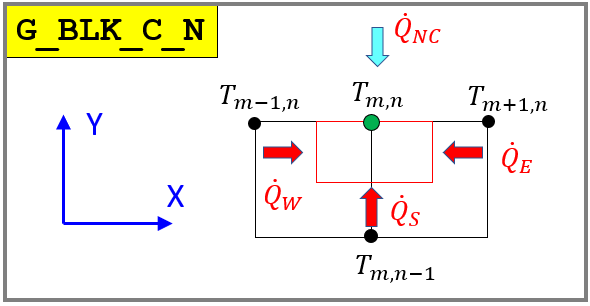

At steady state, the heat balance for this node can be wriiten as:  (**NOTE:**  the length in the $Z$direction is $L$)

- 
$$0=\;\;{\dot{Q} }_S \;+\;\;{\dot{Q} }_E \;+\;{\dot{Q} }_W \;\;\;\;\;\;+\;\;\;\;\;\;{\dot{Q} }_{\textrm{NC}} \;$$


Which we can expand to be:

- 
$$0=\;\;\frac{k\;A_S }{\Delta y}\ldotp \left(T_{m\;,n-1} \;-T_{m\;,n} \right)\;\;\;\;\;\;\;\;\;\;\;\;\;+\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\frac{k\;A_E }{\Delta x}\ldotp \left(T_{m+1\;,n} \;-T_{m\;,n} \right)\;\;\;\;+\;\;\;\;\;\;\;\;\;\;\;\;\;\frac{k\;A_W }{\Delta x}\ldotp \left(T_{m-1\;,n} \;-T_{m\;,n} \right)\;\;\;\;\;+\;\;\;h_{\textrm{ROOF}} {\ldotp A}_{\textrm{NC}} \ldotp \left(T_{\textrm{ROOF}} \;-T_{m\;,n} \right)\;\;\;$$


- 
$$0=\;\;\frac{k\;\left(\Delta x\ldotp L\right)}{\Delta y}\ldotp \left(T_{m\;,n-1} \;-T_{m\;,n} \right)\;\;\;+\;\;\;\frac{k\;\left(\frac{\Delta y\ldotp L}{2}\right)}{\Delta x}\ldotp \left(T_{m+1\;,n} \;-T_{m\;,n} \right)\;\;\;+\;\;\;\frac{k\;\left(\frac{\Delta y\ldotp L}{2}\right)}{\Delta x}\ldotp \left(T_{m-1\;,n} \;-T_{m\;,n} \right)\;\;\;+\;\;\;h_{\textrm{ROOF}} \ldotp \left(\Delta x\ldotp L\right)\ldotp \left(T_{\textrm{ROOF}} \;-T_{m\;,n} \right)$$


We can cancel the common $L$ term and then collect terms as shown below:

- 
$$\left\lbrack \begin{array}{ccccccccc}
0 & 0 & 0 & \left(\frac{k\;\left(\frac{\Delta y}{2}\right)}{\Delta x}\right) & \left(\frac{-k\;\left(\Delta x\ldotp \right)}{\Delta y}+\frac{-k\;\left(\Delta y\right)}{\Delta x}+{-h}_{\textrm{ROOF}\ldotp } \ldotp \Delta x\right) & \left(\frac{k\;\left(\frac{\Delta y}{2}\right)}{\Delta x}\right) & 0 & \left(\frac{k\;\ldotp \Delta x}{\Delta y}\right) & 0
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
T_{m-1,n+1} \\
T_{m,n+1} \\
T_{m+1,n+1} \\
T_{m-1,n} \\
T_{m,n} \\
T_{m+1,n} \\
T_{m-1,n-1} \\
T_{m,n-1} \\
T_{m+1,n-1} 
\end{array}\right\rbrack ={\;-h}_{\textrm{ROOF}\ldotp } \ldotp \Delta x\ldotp T_{\textrm{ROOF}}$$


The above matrix equation has the form  $A\;\ldotp x=b$.  

OK, let's compare the above equations to those produced by the the [`bh_get_node_stencils`](matlab:  edit bh_get_node_stencils) function.

the_A = sten_TAB{"G_BLK_C_N", "s_A"}{1}
the_b = sten_TAB{"G_BLK_C_N", "s_b"}{1}

 **NOTE:  **the expressions for $A\;,b\;$produced by the the [`bh_get_node_stencils`](matlab:  edit bh_get_node_stencils) function, are BOTH just multiplied by $-1$. So? - So, they're still identical to the expressions for $A\;,b\;$that we derived above. 

Finally, if we substitute NUMERIC values for $\Delta x,k,h_{\textrm{ROOF}} ,\;\ldotp \ldotp \ldotp \ldotp \;\textrm{etc}$ we would get:

num_A = sten_TAB{"G_BLK_C_N", ["T_mM1_nP1", "T_m_nP1", "T_mP1_nP1", ...
                               "T_mM1_n"  , "T_m_n"  , "T_mP1_n"  , ...
                               "T_mM1_nM1", "T_m_nM1", "T_mP1_nM1"     ]  }

num_A = sten_TAB{"G_BLK_C_N", "b"}

 And these numeric values would be used to populate the **SYSTEM** version of $A_{\textrm{SYS}} \;\ldotp x_{\textrm{SYS}} =b_{\textrm{SYS}}$